# IV Praktikum 2022

## `Aufgabe 1`

### `Vorbereitungsteil:`


$$|E| = \frac{1}{\sqrt2} 1V,
 $$
 
$$R_1=R_2=R=50 \Omega$$


#### `1. Bestimmen Sie Pmax.`

 
$$P_{max} = \frac{|E|^2}{4R}$$
     
$$|E|^2 = \left( \frac{1V} {\sqrt{2}} \right)^2$$
 
$$ \Rightarrow  $$
   
$$|E|^2 = \frac{1}{2}V^2
$$


$P_{max} = \frac{\frac{1V^2}{2}}{4R} = \frac{1V^2}{8R} = \frac 1 {400}  \frac {V^2} \Omega
$ $=2,5
$mW  

#### `2. Bestimmen Sie S21(jω).`


$$S_{21} = k \frac {U_2} E = 2 \sqrt \frac{R_1} {R_2} \frac {U_2} {U_1} \frac{U_1} {E}$$
  
$$\Rightarrow$$
 
$$S_{21} = 2 \frac {U_2} E$$



$$U_2 = I * \left( R_2+ \frac 1 {j\omega C} \right)^{-1} \\
I = \frac E {R_{ges}}$$
  
$$\Rightarrow$$
 
$$U_2 = \frac E {R_{ges}} * \left( R_2+ \frac 1 {j\omega C} \right)^{-1} \rightarrow  S_{21} = 2 \frac { \left( R_2+ \frac 1 {j\omega C} \right)^{-1}} {R_{ges}}$$



$$R_{ges} =  R + C||R \\
C||R = \frac1 {j \omega C+\frac 1 R}$$
        
$$\Rightarrow
$$
     
$$R_{ges} = R + \frac 1 {j \omega C + \frac 1 R}$$
   
$$\rightarrow$$
 
$$S_{21} = 2 \frac { \left( \frac 1 R+ j\omega C \right)^{-1}} {R+ \frac R {j \omega C R + 1}} $$


syms R omega C real
R_ges = R + 1/(1i*omega*C+1/R);
S_21 = 2*((1/R+1i*omega*C)^-1)/(R+R/(1+1i*omega*C*R)) %2*R/R_ges

$$S\_21 = \frac{2}{\left(\frac{1}{R}+C\,\omega \,\mathrm{i}\right)\,\left(R+\frac{R}{1+C\,R\,\omega \,\mathrm{i}}\right)}$$

simplify(S_21,"Steps",640)

$$ans = \frac{2}{2+C\,R\,\omega \,\mathrm{i}}$$

#### `3. Bestimmen Sie `| `S21(jω)|`² `und AdB(ω).`

simplify(abs(S_21)^2,"Steps",100)

$$ans = \frac{4\,R^{2}\,{\left|C\,R\,\omega -\mathrm{i}\right|}^{2}}{{\left|C\,R\,\omega -2\,\mathrm{i}\right|}^{2}\,{\left|1+C\,R\,\omega \,\mathrm{i}\right|}^{2}\,{\left|R\right|}^{2}}$$

S_21 = 4/(C^2*R^2*omega^2 + 4) - (2i*C*R*omega)/(C^2*R^2*omega^2 + 4)

$$S\_21 = \frac{4}{C^{2}\,R^{2}\,\omega^{2}+4}-\frac{2\,C\,R\,\omega \,\mathrm{i}}{C^{2}\,R^{2}\,\omega^{2}+4}$$

simpS21_abs_quad = (4*C^2*R^2*omega^2)/(C^2*R^2*omega^2 + 4)^2 + 16/(C^2*R^2*omega^2 + 4)^2

$$simpS21\_abs\_quad = \frac{16}{{\left(C^{2}\,R^{2}\,\omega^{2}+4\right)}^{2}}+\frac{4\,C^{2}\,R^{2}\,\omega^{2}}{{\left(C^{2}\,R^{2}\,\omega^{2}+4\right)}^{2}}$$

A_db = 10*log10((C^2*R^2*omega^2 + 4)^2/(4*C^2*R^2*omega^2+16))

$$A\_db = \frac{10\,\log\left(\frac{{\left(C^{2}\,R^{2}\,\omega^{2}+4\right)}^{2}}{4\,C^{2}\,R^{2}\,\omega^{2}+16}\right)}{\log\left(10\right)}$$

simA_db = simplify(A_db,"Steps",100)

$$simA\_db = \frac{10\,\log\left(\frac{C^{2}\,R^{2}\,\omega^{2}}{4}+1\right)}{\log\left(10\right)}$$

#### `4. Zeichnen Sie AdB(ω) qualitativ.`

A_dB = symfun(simA_db,[C,R,omega])

$$A\_dB(C, R, omega) = \frac{10\,\log\left(\frac{C^{2}\,R^{2}\,\omega^{2}}{4}+1\right)}{\log\left(10\right)}$$

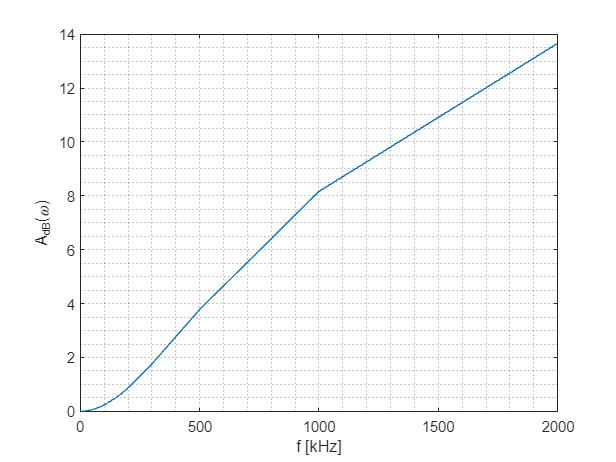

f = [10 50 90 100 150 170 180 200 300 500 1000 2000]*1e3; %kHZ

%f = 1000:1000:2000000;
plot(f./10^3,A_dB(15*10^-9,50,2*pi*f)) %C-Wert aus letzte Aufgabe
xlabel ("f [kHz]")
ylabel("A_{dB}(\omega)")
grid("minor")

#### `5. Handelt es sich um ein Hochpass- oder ein Tiefpassfilter? Begründen Sie Ihre Antwort.`

Tiefpass, da tiefe Frequ. eine geringe Dämpfung haben und hohe Freq. eine hohe Dämpfung.

#### `6. Bestimmen Sie C in Abhängigkeit von der Durchlasskreisfrequenz` $\omega_g$ `und dem Rippel im Durchlassbereich` $A_D$. 

*Nutzen Sie dazu den Ansatz *$A_{dB}(\omega_g) = A_D$. 

syms A_D
formula = solve(simA_db==A_D,C,"ReturnConditions",true);
formula.C(2)

$$ans = \frac{2\,\sqrt{10^{A_{D}/10}-1}}{R\,\omega }$$

#### `7. Bestimmen Sie den Wert von C für f` $(f_g = 100kHz)$ `und` A $(A_D = 0.28dB)$. `Runden Sie Ihr Ergebnis auf den nächsten in der E6-Bauteilreihe1 verfügbaren Wert.`

double(subs(formula.C(2),[A_D R omega], [0.28 50 2*pi*10^5]))*1e9  %%F --> nF

ans = 16.4288

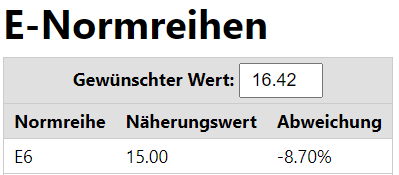

C_value = 15 %nF

C_value = 15

### `Praxisteil`

#### `Aufgabe 7 Machen Sie ein Kamerabild von Ihrem Aufbau auf dem Breadboard. Und fügen Sie es dem Bericht bei.` 

Aufbau Bild:

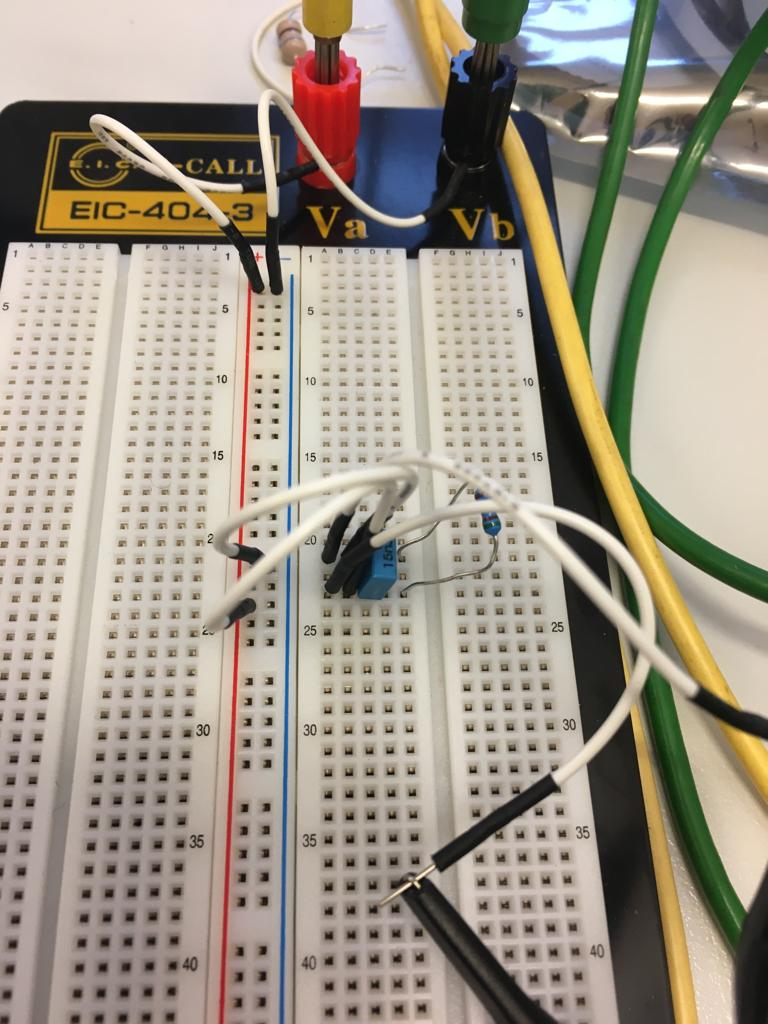

#### `Aufgabe 8/9/11 Beschreiben Sie Ihre Vorgehensweise bei der Einstellung des Oszilloskop:`

Vorgehensweiße:

Zuerst muessen die Vorgegeben Werte auf dem Generator einigestellt werden. 100kHz und 1VPP:

Beim Anschalten des Ozsi. wird das Signal mit dem Auto-Detect Knopf detektiert. Fuer die Ablesung der Amplitude muss noch vertikal rein gezoomt werden.

Die Amplitude hatte ein Wert von 58.8 mW und eine Periodendauer von 10$\mu s$ (siehe Screenshot). 

Periodendauer $10\mu s$

Amplitude: $58.8 mW$

#### `Aufgabe 10/12 Zeichnen Sie die abgelesene Amplitude und die Periodendauer gut sichtbar in Ihrer Abbildung ein.`     

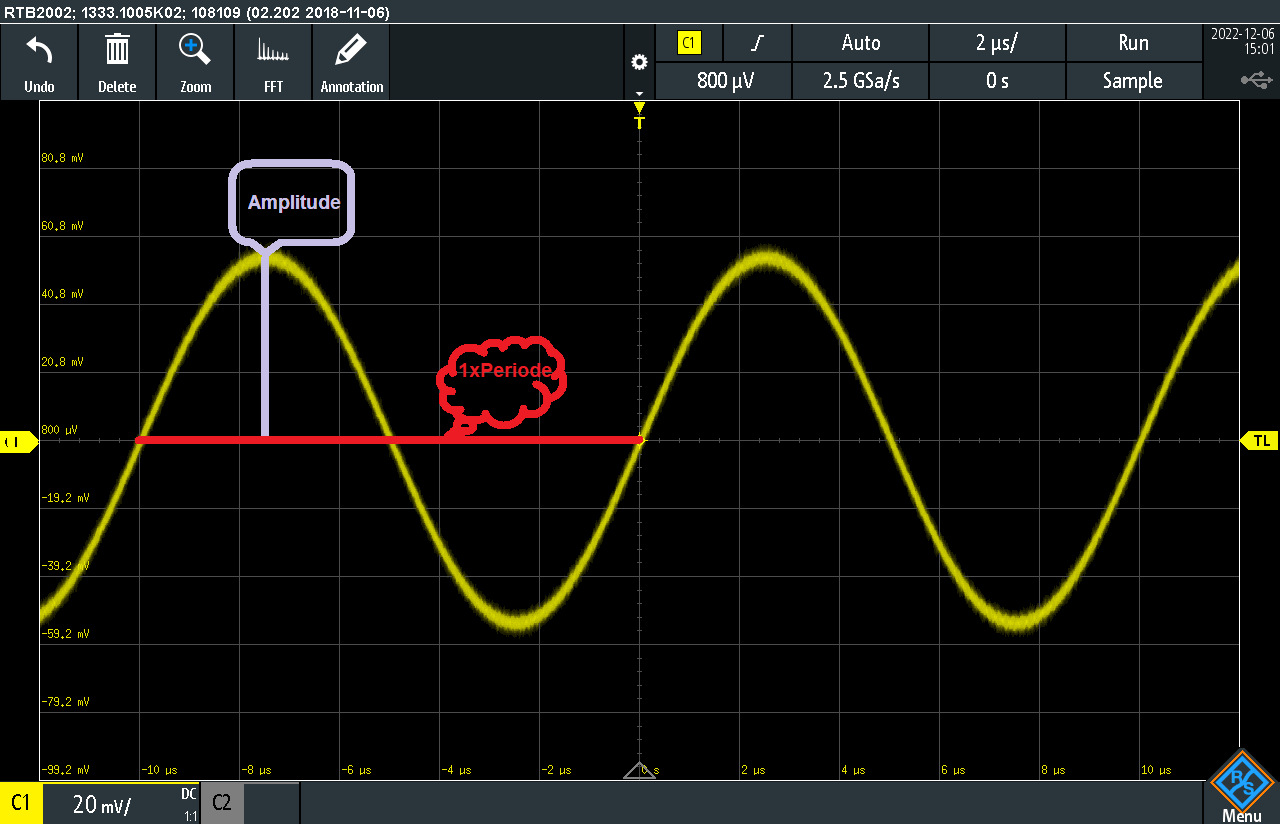

#### `Berechnen ``Sie die Frequenz` $f$ `aus der Periodendauer`

$f = \frac 1 {T}$ mit  $T = 10 \mu s$ 

fg = 1/(10^-5)/1000 %kHz

fg = 100.0000

#### `Aufgabe 13 Messen Sie den Betrag von U2 für die in Tabelle 1 aufgelisteten Frequenzen` $f$.

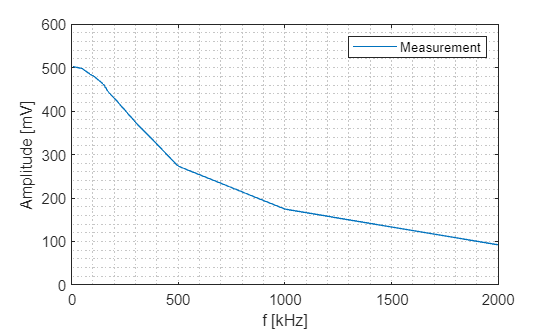

clf
f = [10 50 90 100 150 170 180 200 300 500 1000 2000]; %kHZ --Tabelle
Periodendauer = f.^-1*1000; %Mikrosekundend
Amp = [502 498 484 482 462 445.9 440.02 430.22 374.36 273.42 174.44 92.12]; %mW
plot(f,Amp)
xlabel("f [kHz]")
ylabel("Amplitude [mV]")
grid("minor")
legend("Measurement")

Mit steigender Frequenz sinkt die Amplitdue. (Tiefpass verhalten)

#### `Aufgabe 14 Rechnen Sie die gemessenen Beträge von` $U_2$ `in Werte der Transmittanz` $|S_{21}(j\omega )|$ `um.`

S21_value = 2*Amp./1e3

S21_value =     1.0040    0.9960    0.9680    0.9640    0.9240    0.8918    0.8800    0.8604    0.7487    0.5468    0.3489    0.1842


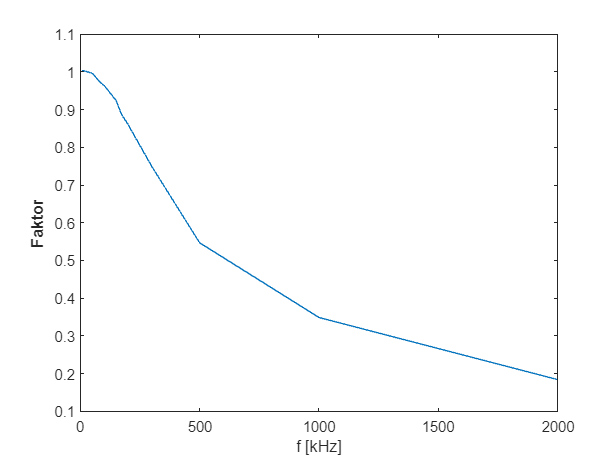

clf
plot(f,S21_value)
xlabel("f [kHz]")
ylabel("\bf{Faktor}")

#### `Aufgabe 15 Rechnen Sie die Werte von` |S21| `in Werte der Betriebsdämpfung` $A_{dB}(\omega )$ `um`.

clf
A_dB_value = double(10*log10(abs(S21_value).^-2))

A_dB_value =    -0.0347    0.0348    0.2825    0.3185    0.6866    0.9947    1.1100    1.3056    2.5136    5.2428    9.1465   14.6923


#### `Aufgabe 16 Stellen Sie die Werte von AdB` $A_{dB}(\omega )$ `in einem Diagramm über die Frequenz dar.`

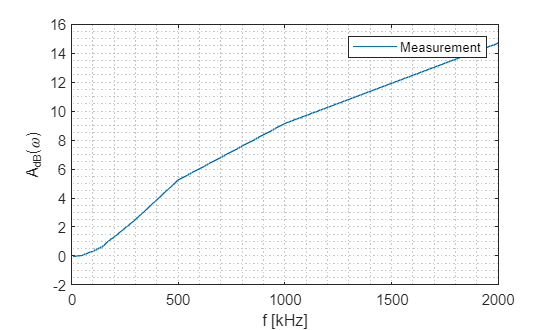

plot(f,A_dB_value)
grid("minor")
xlabel("f [kHz]")
ylabel("A_{dB}(\omega)")
legend("Measurement")

#### `Aufgabe 17 Vergleichen Sie die Darstellung mit dem im Vorbereitungsteil skizzierten Verlauf von AdB.` $A_{dB}(\omega )$.

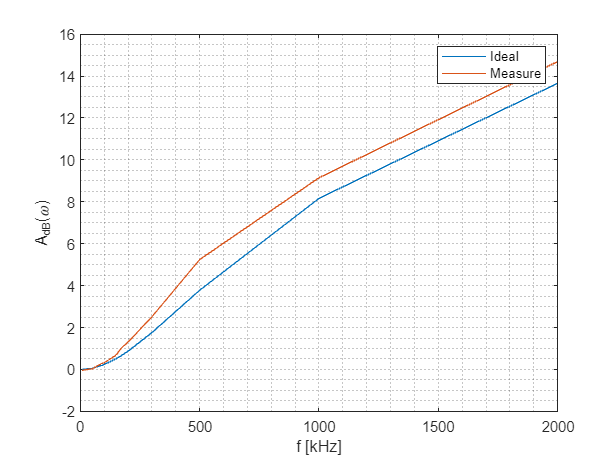

clf
plot(f,A_dB(15*10^-9,50,2*pi*f*10^3)) %C-Wert aus letzte Aufgabe
xlabel ("f [kHz]")
ylabel("A_{dB}(\omega)")
grid("minor")
hold on
plot(f,A_dB_value)
legend("Ideal", "Measure")
hold off

Die Abweichungen lassen sich unter anderem durch Messrauschen und nicht Idealen Komponenten (Abweichungsnormen) erklären.

## `Aufgabe 2`

### `Vorbereitungsteil:`

#### `1.Entwerfen Sie ein Cauer Tiefpassfilter 3.Ordnung:` $\Omega_S \leq 2$ $a_S \geq 28dB$ $R_1 = R_2 = 50\Omega$

    $\Omega_s \leq 2$, $n=3$ --> C0325 (siehe Filtertabelle)

#### `2. Welche Filterkatalognummer und welches Theta` $\Theta$ `haben Sie gewählt, welches r?` $r_1, r_2$? 

    
$$\Theta = 30\degree $$
 
$$r_1 = r_2 = 1$$


#### `3. Zeichnen Sie den Schaltplan des gewählten Filters.`

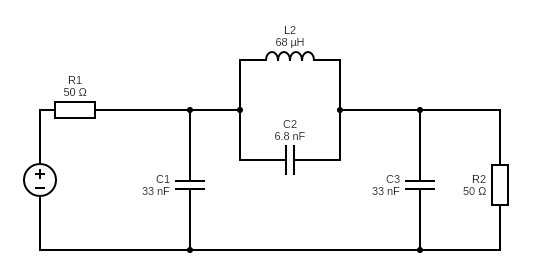

#### `4. Nun sei weiterhin gegeben fs.` $f_S = 200kHz$ `Berechnen Sie die erforderlichen Bauteilwerte des Filters.`

    
$$\Omega_s = \frac {f_s} {f_g}$$
    
$$\longrightarrow$$
 
$$f_g = \frac {f_s}{\Omega_s}$$


f_g = 200/2 %kHz

f_g = 100


$$f_g = 100kHz$$


L_0 = 50/(2*pi*f_g);
L_2 = 0.962438*L_0 

L_2 = 0.0766

C_0 = 1/(50*2*pi*f_g*10^3);
C_n = [1.203011 0.201627 1.203011]*C_0*10^9

C_n =    38.2930    6.4180   38.2930


#### `5. Runden Sie die Bauteilwerte auf die nächsten in der E6-Bauteilreihe verfügbaren Werte.` 

**    E6 Bauteil**: $L_2 = 0.068mH$

**    E6 Bauteil: **$C_1 =  33 nF$        $C_2 = 6.8nF$        $C_3=33nF$

#### `6. ``Rechnen Sie die normierte Unendlichkeitsstelle` $\Omega_{\infty2}$ `und Nullstelle` $\Omega_{02}$ `in die zugehörigen Frequenzen` $f_{\infty2}$ $f_{02}$

    
$$\Omega_{\infty 2} = 2.270068086$$
      
$$\Omega_{02} = 0.8810308431$$
      

    
$$\Omega_{\infty2} = \frac {f_{\infty2}} {f_g}$$
        
$$\Rightarrow$$
        
$$f_{\infty2} = \Omega_{\infty2} \cdot f_g = 227.0068kHz$$
         

    
$$\Omega_{02} = \frac {f_{02}} {f_g}$$
          
$$\Rightarrow$$
       
$$f_{02} = \Omega_{02} \cdot f_g = 88.1030kHz$$


Omega_inf2 = 2.270068086*f_g %kHz

Omega_inf2 = 227.0068

Omgea_02 = 0.88103008431*f_g %kHz

Omgea_02 = 88.1030

### `Praxisteil`

#### 2. Machen Sie ein Kamerabild von Ihrem Aufbau auf dem Breadboard und fügen Sie es dem Bericht bei.

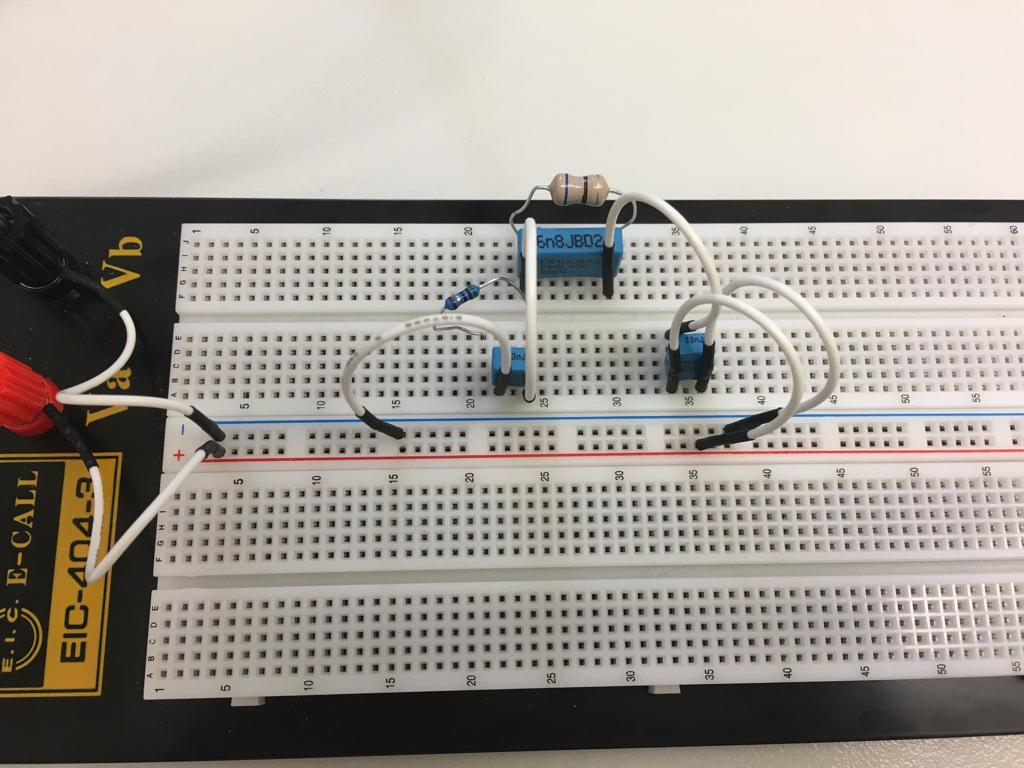

#### 3. Messen Sie den Betrag von U2 für die in Tabelle 2 aufgelisteten Frequenzen f.

f_expand         = [10   50 Omgea_02  90 100 150    170    180   200 Omega_inf2    300    500    1000 2000]; %kHZ --Tabelle
cauer_Amp_expand = [494 480 U2f_02 486 484 211.19 110.25 77.8 35.966  U2f_inf  21.658 24.206 4.263 1.323]; %mV
f                = [10   50  90 100 150    170    180  200      300    500    1000 2000]; %kHZ --Tabelle
cauer_Amp        = [494 480 486 484 211.19 110.25 77.8 35.966  21.658 24.206 4.263 1.323] %mV

cauer_Amp =   494.0000  480.0000  486.0000  484.0000  211.1900  110.2500   77.8000   35.9660   21.6580   24.2060    4.2630    1.3230


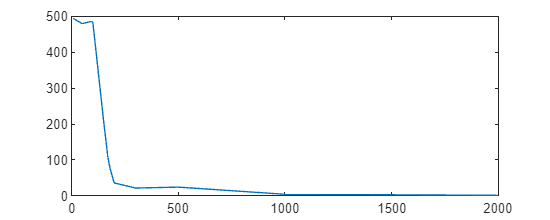

clf
plot(f,cauer_Amp)

#### 4. Messen Sie den Betrag von U2 an der Unendlichkeitsstelle f∞2 und Nullstelle f02. 

U2f_inf = 10.29/2

U2f_inf = 5.1450

U2f_02 = 968/2

U2f_02 = 484

#### 5. Auswertung: Rechnen Sie die gemessenen Betr¨age von U2 in Werte der Transmit�tanz |S21(jω)| um. 

cauer_S21 = 2*cauer_Amp/1e3 

cauer_S21 =     0.9880    0.9600    0.9720    0.9680    0.4224    0.2205    0.1556    0.0719    0.0433    0.0484    0.0085    0.0026


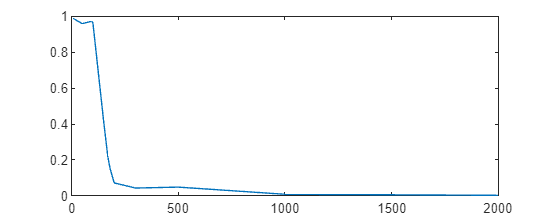

cauer_S21expand = 2*cauer_Amp_expand/1e3;

plot(f,cauer_S21)

#### 6. Rechnen Sie die Werte von |S21(jω)| in Werte der Betriebsd¨ampfung AdB(ω) um.

cauerA_dB = 10*log10(cauer_S21.^-2);
cauerA_dBexpand = 10*log10(cauer_S21expand.^-2)

cauerA_dBexpand =     0.1049    0.3546    0.2825    0.2467    0.2825    7.4859   13.1318   16.1598   22.8616   39.7517   27.2670   26.3009   41.3851   51.5482


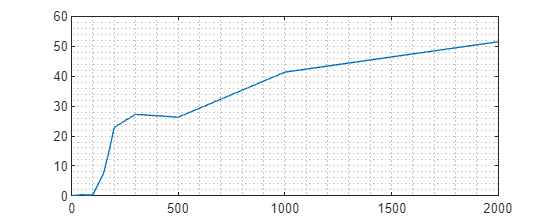

plot(f,cauerA_dB)
grid minor

set(gcf,"position",[0,0,500,200])

#### 7. Stellen Sie die Werte von AdB(ω) zusammen mit den Werten von AdB(ω) aus Aufgabe 1 in einem Diagramm über der Frequenz dar.

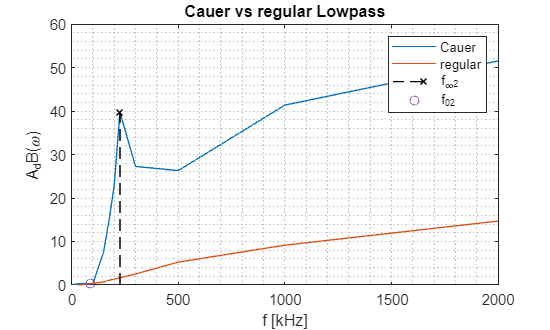

clf
plot(f_expand,cauerA_dBexpand)
grid minor
xlabel("f [kHz]")
ylabel("A_dB(\omega)")
hold on
plot(f,A_dB_value)
stem(Omega_inf2,10*log10((2*U2f_inf*10^-3)^-2),"blackX",LineWidth=1,LineStyle="--")
plot(Omgea_02, 10*log10((2*U2f_02*10^-3)^-2),"O")
ylim([0,60])
hold off
legend("Cauer","regular","f_{\infty2}", "f_{02}")
title("Cauer vs regular Lowpass")

set(gcf,"position",[0,0,500,300])

#### 8.Vergleichen Sie die beiden Verläufe von AdB(ω) von den zwei Aufgaben

Der reguläre Tiefpass ist scheiße.....Der Cauer-Tiefpass reagiert viel schneller und sperrt somit schnell die gewünschte Frequ. im vergleich zum regulären Tiefpass.

#### 9. Vergleichen Sie den Verlauf von AdB(ω) mit dem Dämpfungsverlauf von dem Filterkatalog an der Nullstelle f02 und der Unendlichkeitsstelle f∞2.

Rasanter Abstieg....

#### 10. Werden die Anforderungen an den Filterentwurf in der Praxis erfüllt? Bestimmen Sie die tatsächlichen Werte von aS und ΩS aus Ihren Messwerten und vergleichen Sie diese mit den Anforderungen.

50dB 

#### 11. Bauen Sie das Tiefpassfilter zu einem Hochpassfilter mit gleicher Ordnung und gleichem Typ (Cauer) um. Verwenden Sie die selben Bauteile.

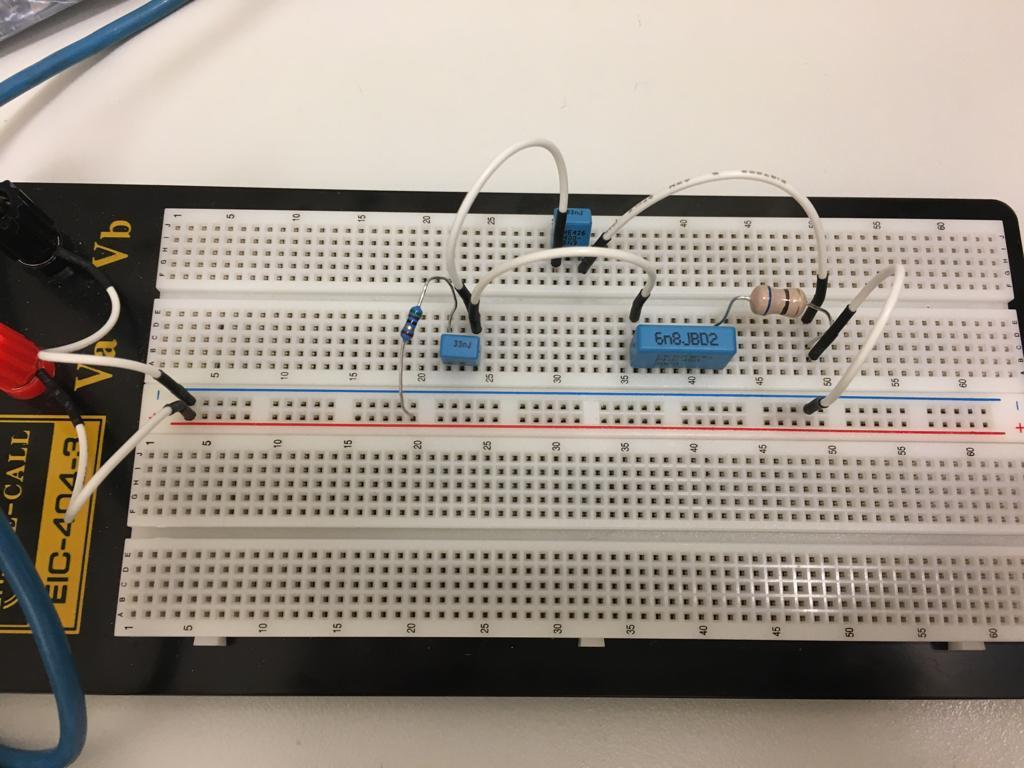

#### 12. Begründen Sie Ihr Vorgehen beim vorherigen Aufgabenteil. Geben Sie die Schaltung und den allgemeingultigen Dämpfungsverlauf des Hochpassfilters an.

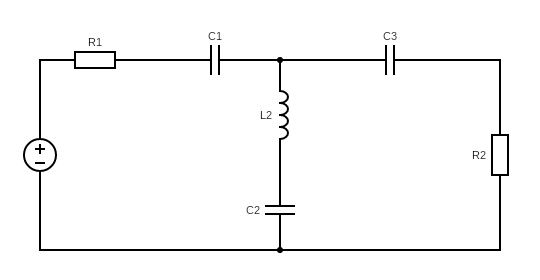

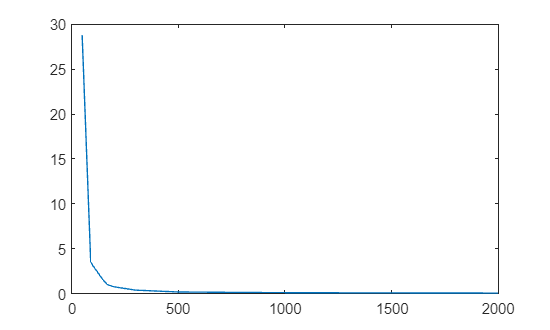

plot(f(2:end),A_dB_value(2:end).^-1)